# **FORÅR 2017 EKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

En diskret stokastisk variabel $X$har følgende fordelingsfunktion $F_X \left(x\right)$.

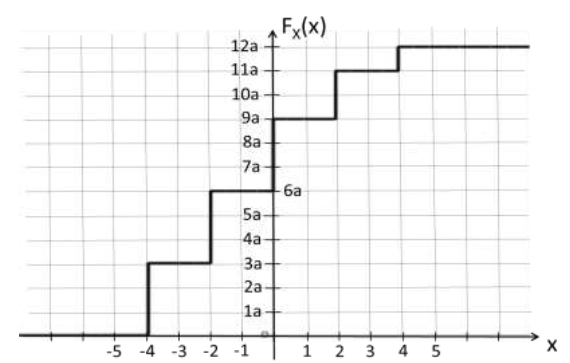

## 1.1 GYLDIG FORDELINGSFUNKTION

For at bestemme om $F_{X\left(x\right)}$er en gyldig fordeligsfunktion anvendes, at 


$$\underset{x\to \infty }{\mathrm{lim}} F_X \left(x\right)=1$$


Det antages at outputtet af fordelingsfunktione ikke antager værdier større end 12a, der gælder følgende.


$$\underset{x\to \infty }{\mathrm{lim}} F_X \left(x\right)=12a$$


Dermed givet det, at


$$a=\frac{1}{12}$$


Fordelingsfunktionen er dermed gældende for værdien af $a$ leg med $\frac{1}{12}$.

## 1.2 TÆTHEDSFUNKTION

For at bestemme tæthedsfunktione $f_X \left(x\right)$anvendes, at størrelse af trinene i fordelingsfunktion er tæthedsfunktionen. Dermed opnåes, at


$$f_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
3a & x=-4\\
3a & x=-2\\
3a & x=0\\
2a & x=2\\
1a & x=4\\
0 & \mathrm{ellers}
\end{array}\right\rbrack \right\rbrace$$


## 1.3 MIDDELVÆRDI

For at bestemme middelværdien anvendes, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


a = 1/12;

X = [-4, -2, 0, 2, 4];
P = [3*a, 3*a, 3*a, 2*a, 1*a];

EstimationX = 0;

for n = 1:length(P)
    EstimationX = EstimationX + (X(n) * P(n));
end

sym(EstimationX)

$$ans = -\frac{5}{6}$$

Middelværdien er dermed bestemt til at være $-\frac{5}{6}\ldotp$

## 1.4 VARIANS

For at bestemme variansen anvendes, at


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


EstimationXSquared = 0;

for n = 1:length(P)
    EstimationXSquared = EstimationXSquared + (X(n)^2 * P(n));
end

VarianceX = EstimationXSquared - EstimationX^2

VarianceX = 6.3056

Variansen er dermed bestemt til at være 6.3056.

# **2 SANDSYNLIGHED**

I juni måned (30 dage) regner det i gennemsnit 20% af dagene i den første halvdel af måneden og 30% af dagene i den sidste halvdel af måneden.

$A:\mathrm{REGN}$ - $\overline{A} :\mathrm{IKKE}\;\mathrm{REGN}$

$B:1\ldotp \mathrm{HALVDEL}$ - $\overline{B} :2\ldotp \mathrm{HALVDEL}$


$$P\left(A|B\right)=0\ldotp 2$$



$$P\left(A|\overline{B} \right)=0\ldotp 3$$



$$P\left(B\right)=P\left(\overline{B} \right)=0\ldotp 5$$


## **2.1 ANTAL DAGE**

Først findes den totale sandsynlighed for A, givet ved


$$P\left(A\right)=P\left(A|B\right)\cdot P\left(B\right)+P\left(A|\overline{B} \right)\cdot P\left(\overline{B} \right)$$


DaysInMonth = 30;

AGivenB = 0.2;
AGivenNotB = 0.3;
B = 0.5;

NotB = 0.5;

A = AGivenB * B + AGivenNotB * NotB;
DaysWithRain = A * 30

DaysWithRain = 7.5000

Dermed er det bestemt at der regner i gennemsnit 7.5 i juni måned.

## 2.2 BETINGET SANDSYNLIGHED

For at bestemme sandsynligheden for at være i den sidste del af måneden givet at der er regnvejr anvendes, at


$$P\left(\overline{B} |A\right)=\frac{P\left(A|\overline{B} \right)\cdot P\left(\overline{B} \right)}{P\left(A\right)}$$


NotBGivenA = (AGivenNotB * B) / A

NotBGivenA = 0.6000

Dermed er sandsynligheden bestemt til at være 0.6 altså 60%.

## 2.3 REGN HØJST EN DAG

For at bestemme sandsynligheden for højst en dag med regnes observeres, at 


$$P\left(\mathrm{dage}\le 1|B\right)=P\left(0\;\mathrm{dage}\;|\;B\right)+P\left(1\;\mathrm{dag}|B\right)$$


Dertil anvendes ikke sorteret rækkefølge uden tilbagelægning. Succes ses som


$$P\left(A|B\right)=p=0\ldotp 2$$


hvor fiasko ses som 


$$P\left(\overline{A} |B\right)=1-p=0\ldotp 8$$


Sandsynligheden kan bestemmes som 


$$P\left(k\right)=\frac{n!}{k!\cdot \left(n-k\right)!}p^k q^{{\;}^{n-k} }$$


DaysWithinHalfMonth = DaysInMonth / 2;

Bernoulli = @(k, n) (factorial(n) / (factorial(k) * factorial(n-k))) * (AGivenB^k) * ((1-AGivenB)^(n-k));

Bernoulli(1, 15) + Bernoulli(0, 15)

ans = 0.1671

Dermed er sandsynligheden for regn højst en dag bestemt til at være 0.1671 altså 16.71%.

# **3 STOKASTISK PROCESS**

En kontinuert stokastisk process $X\left(t\right)$givet ved


$$X\left(t\right)={\left(-1\right)}^n +W$$


hvor W er i.i.d. Gaussisk fordelte stokastiske variable W ~ N(0, 0.25) og n uafhængigt kan antage værdierne 0 og 1 med lige stor sandsynlighed.�(0; 0,25), og n uafhængigt kan . 

##  3.1 REALISERING

Skitsering af realiseringen laves i matlab.

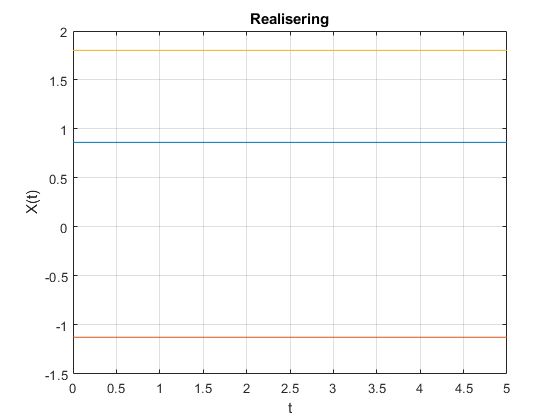

t = 0:1:5;

mu = 0;
sigma = sqrt(0.25);

Realisation = [[],[],[]];


for n = 1:3
    Realisation(n, :) = (-1)^(randi([0, 1])) + (ones(1, length(t)) * (sigma * randn + mu));
end

figure(1)
plot(t, Realisation(1, :));
hold on
plot(t, Realisation(2, :));
plot(t, Realisation(3, :));
grid on
title('Realisering')
ylabel('X(t)')
xlabel('t')
hold off

## 3.2 MIDDEL OG VARIANS AF REALISERING

Real.Mean = mean(Realisation(1, :));
Real.Variance = round(var(Realisation(1, :)), 10);

Real

Real = struct with fields:
        Mean: 0.8630
    Variance: 0


Middelværdi og variansen for en udvalgt realisering er bestemt til at være værdierne vist ovenfor.

## 3.3 ENSEMBLE MIDDELVÆRDI OG VARIANS

For at bestemme middelværdien for ensemble anvendes, at


$$E\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack {\left(-1\right)}^n +W\right\rbrack =E\left\lbrack {\left(-1\right)}^n \right\rbrack +E\left\lbrack W\right\rbrack$$



$$E\left\lbrack X\left(t\right)\right\rbrack ={\left(-1\right)}^0 \cdot P\left(n=0\right)+{\left(-1\right)}^1 \cdot P\left(n=1\right)+E\left\lbrack W\right\rbrack$$



$$P\left(n=0\right)=P\left(n=1\right)=\frac{1}{2}$$


Ensemble.MeanValue = ((-1)^0) * 1/2 + ((-1)^1) * 1/2 + mu;

Variansen kan bestemmes som


$$\mathrm{Var}\left(X\left(t\right)\right)=\mathrm{Var}\left\lbrack {\left(-1\right)}^n +W\right\rbrack =\mathrm{Var}\left\lbrack {\left(-1\right)}^n \right\rbrack +\mathrm{Var}\left\lbrack W\right\rbrack$$



$$\mathrm{Var}\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack {\left({\left(-1\right)}^n \right)}^2 \right\rbrack -E{\left\lbrack {\left(-1\right)}^n \right\rbrack }^2 +\mathrm{Var}\left\lbrack W\right\rbrack$$


Ensemble.Variance = (((-1)^0)^2 * 1/2 + ((-1)^1)^2 * 1/2) ...
    + (((-1)^0) * 1/2 + ((-1)^1) * 1/2)^2 + sigma^2;

Ensemble

Ensemble = struct with fields:
    MeanValue: 0
     Variance: 1.2500


Dermed er middelværdien bestemt til at være 0 og variansen bestemt til at være 1.25.

## 3.4 PROCESSEN

Processen er WSS da middelværdien og variansen er uafhængig af tiden. Dog er processen ikke ergodisk da den temporale middelværdi samt varians er forskellige fra ensemble værdierne.

# **4 STATISTIK**

En kvalitetskontrol måler præcisionen af to forskellige typer gps’er. For begge typer blev målt afvigelsen mellem deres faktiske position $d_{\mathrm{faktisk}}$og gps’ens angivelse $d_{\mathrm{gps}}$.


$$d_i =|d_{i,\mathrm{gps}} -d_{i,\mathrm{faktisk}} |$$


Det kan antages at afvigelserne er normalfordelte. Der er testet 10 gps enheder af type 1 og 12 gps enheder af type 2. For type 1 var middelafvigelsen $\hat{\mu_1 } =5\ldotp 21m$ med en estimeret varians $s_1^2 =1\ldotp 33m^2$. For type 2 var middelafvigelsen $\hat{\mu_2 } =4\ldotp 18m$ med en estimeret varians $s_2^2 =0\ldotp 89m^2$.

TypeOne = struct('Mean', 5.21, 'Variance', 1.33, 'Amount', 10);
TypeTwo = struct('Mean', 4.18, 'Variance', 0.89, 'Amount', 12);

## 4.1 HYPOTESER

Der opstilles en hypotese test for at bestemme om middelværdien af de to grupper er den samme.


$$H_0 :$$
  
$$\mu_1 =\mu_2$$



$$H_1 :$$
  
$$\mu_1 \not= \mu_2$$


## 4.2 ESTIMERING AF FORSKEL I MIDDELVÆRDI

Estimeringen af forskellen i middelværdierne kan bestemmes som følgende.


$$\delta^ˆ =|\overline{x_1 } -\overline{x_2 } |$$


Delta = abs(TypeOne.Mean - TypeTwo.Mean)

Delta = 1.0300

Forskellen i middelværdierne er bestemt til at være 1.03.

## 4.3 ESTIMERING AF VARIANSEN FOR FORSKELLEN

For at bestemme forskellen i variansen anvendes, at


$$s^2 =\frac{1}{n_1 +n_2 -2}\left\lbrack \left(n_1 -1\right)\cdot s_1^2 +\left(n_2 -1\right)\cdot s_2^2 \right\rbrack$$


PooledVariance = (1 / (TypeOne.Amount + TypeTwo.Amount -2)) ...
    * ((TypeOne.Amount - 1)*TypeOne.Variance + (TypeTwo.Amount -1)*TypeTwo.Variance)

PooledVariance = 1.0880

Forskellen i variansen er dermed bestemt til at være 1.088.

## **4.4 T-TEST**

Der anvendes nu en t-test til test af hypotesen. For at undersøge om NULL hypotesen kan afvises med et signifikansniveau på 0.05 anvendes, at


$$t=\frac{\left(\overline{x_1 } -\overline{x_2 } \right)-\delta }{s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}},\;\;p=2\cdot \left(1-t_{\mathrm{cdf}} \left(|t|,n_1 +n_2 -2\right)\right)$$


t = (Delta - 0) / (sqrt(PooledVariance) * sqrt(1/TypeOne.Amount + 1/TypeTwo.Amount));

p = 2 * (1 - tcdf(abs(t), TypeOne.Amount + TypeTwo.Amount -2))

p = 0.0319

NULL hypotesen kan afvises da $p<0\ldotp 05$. 

## **4.5 KONFIDENSINTERVAL**

For at finde 95% konfidens intervallet for $\delta$ anvendes, at 


$$\delta_{\pm } =\left(\overline{x_1 } -\overline{x_2 } \right)\pm t_0 \cdot s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}$$


TZero = tinv(0.975, TypeOne.Amount + TypeTwo.Amount - 2);

Step = TZero * sqrt(PooledVariance) * sqrt(1/TypeOne.Amount + 1/TypeTwo.Amount);

Interval.Min = Delta - Step;
Interval.Max = Delta + Step;

Interval

Interval = struct with fields:
    Min: 0.0984
    Max: 1.9616


Konfidensintervallet for $\delta$ er dermed bestemt til at være [0.0984; 1.9616].